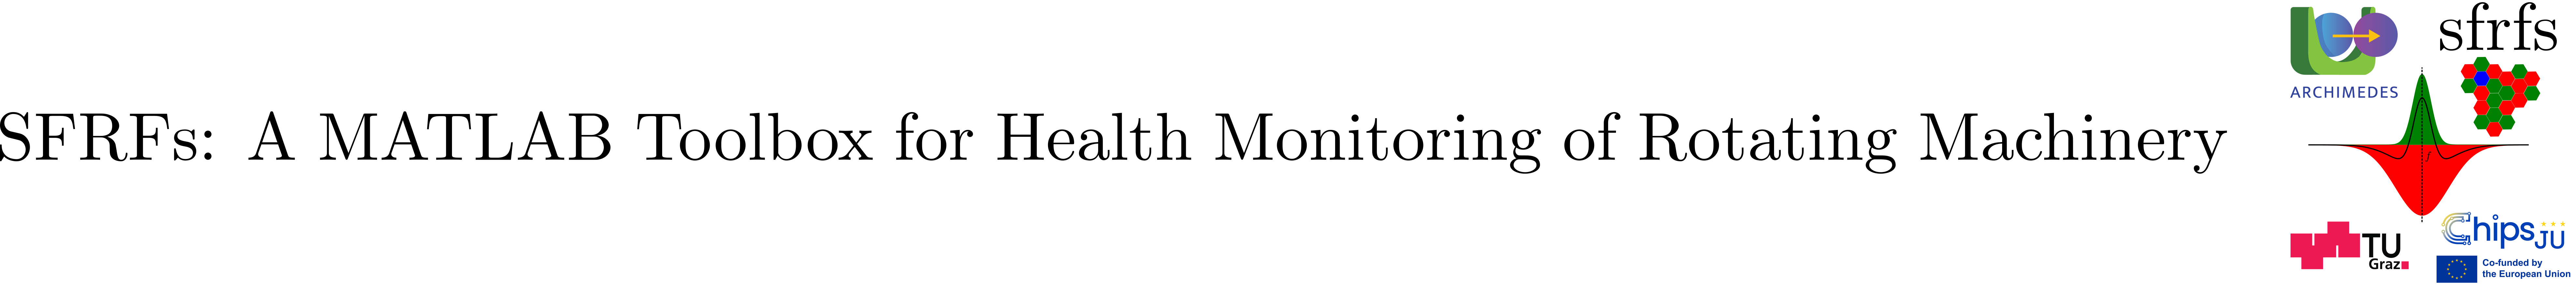

# FaultConditionSelector

## Summary

Resolve a fault-condition key `(FaultGroup, Speed, Load)` to a unique row in a fault-condition table.

## Description

`FaultConditionSelector` provides static helpers for selecting a unique record from a fault-condition table using the key `(FaultGroup, Speed, Load)`. The operating point is provided as an `OperatingConditionSelection` instance, and

the fault group is provided explicitly.

The selector relies on column-name constants defined by [`FaultConditionTableMetaSchema`](matlab:open('./FaultConditionTableMetaSchema.mlx')) (tables package) to avoid hard-coded variable names and to keep selection logic stable if column naming is refactored.

If the selection does not match any row, or if it matches more than one row, the class throws a descriptive error with a stable error identifier.

### Public methods

#### `selectRow`

Resolve a unique row index.

**Syntax (by example)**

        `sel = OperatingConditionSelection(speed = speedHz, load = loadkN);`

        `idx = tables.FaultConditionSelector.selectRow( ...`

        `    tbl, faultGroup = faultGroup, selection = sel);`

**Inputs**

- `tbl` (table): fault-condition table.

- `faultGroup` (double scalar): fault group identifier.

- `selection` (`OperatingConditionSelection`): operating point.

**Output**

- `idx` (double scalar): unique matching row index.

**Errors**

- `sfrfs:tables:FaultConditionSelector:MissingColumn - `Required key column is not present.

- `sfrfs:tables:FaultConditionSelector:NoMatch - `No row matches the requested key.

- `sfrfs:tables:FaultConditionSelector:AmbiguousMatch - `More than one row matches the requested key.

#### `extractRecordStruct`

Extract a matching row as a struct.

**Syntax (by example)**

        `sel = OperatingConditionSelection(speed = speedHz, load = loadkN);`

        `[rec, idx] = tables.FaultConditionSelector.extractRecordStruct( ...`

        `    tbl, faultGroup = faultGroup, selection = sel);`

**Outputs**

- `rec` (struct): struct with fields matching the table variables.

- `idx` (double scalar): matching row index.

### See also

[FaultFrequencyBands](matlab:open('./FaultFrequencyBands.mlx')), [BearingFrequencyBands](matlab:open('./BearingFrequencyBands.mlx')), [FaultConditionTableMetaSchema](matlab:open('./FaultConditionTableMetaSchema.mlx')), [OperatingConditions](matlab:open('./OperatingConditions.mlx')), [OperatingConditionSelection](matlab:open('./OperatingConditionSelection.mlx'))

## **Example**

import tables.FaultConditionTableMetaSchema

% Fault type and group 
ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;
faultGroup = BearingFrequencyBands.faultTypeGroups(ft);
desc = BearingFrequencyBands.faultTypeDescriptions(ft);

% Build a minimal fault-condition table
ms = FaultConditionTableMetaSchema;
tbl = table();
tbl.(ms.FAULTGROUP)  = faultGroup;
tbl.(ms.SPEED)       = 35;
tbl.(ms.LOAD)        = 12;
tbl.(ms.DESCRIPTION) = desc;

disp(tbl);

    FaultGroup    Speed    Load       Description    
    __________    _____    ____    __________________

        1          35       12     "Outer Race Fault"




% Select operating condition
sel = OperatingConditionSelection(speed = 35, load = 12);

% Resolve unique row
idx = FaultConditionSelector.selectRow( ...
    tbl, faultGroup = faultGroup, selection = sel);

disp("Selected row index: " + idx);

Selected row index: 1


disp(tbl(idx, :));

    FaultGroup    Speed    Load       Description    
    __________    _____    ____    __________________

        1          35       12     "Outer Race Fault"




% Extract record as struct
[rec, idx2] = FaultConditionSelector.extractRecordStruct( ...
    tbl, faultGroup = faultGroup, selection = sel);

disp("Extracted record:");

Extracted record:


disp(rec);

     FaultGroup: 1
          Speed: 35
           Load: 12
    Description: "Outer Race Fault"



## API documentation

### MATLAB help

help FaultConditionSelector

Running TestFaultConditionSelector
....
Done TestFaultConditionSelector
__________



## Source code

The source of the class can be found in [FaultConditionSelector](matlab:open('../../FaultConditionSelector.m')).

## Test

The unit test for this class can be found in [TestFaultConditionSelector](matlab:open('../../../tests/TestFaultConditionSelector.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestFaultConditionSelector');

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestFaultConditionSelector/testExtractRecordStructHappyPath                      | Passed
TestFaultConditionSelector/testExtractRecordStructNoMatchThrows                  | Passed
TestFaultConditionSelector/testExtractRecordStructAmbiguousMatchThrows           | Passed
TestFaultConditionSelector/testExtractRecordStructMissingColumnThrows            | Passed



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).